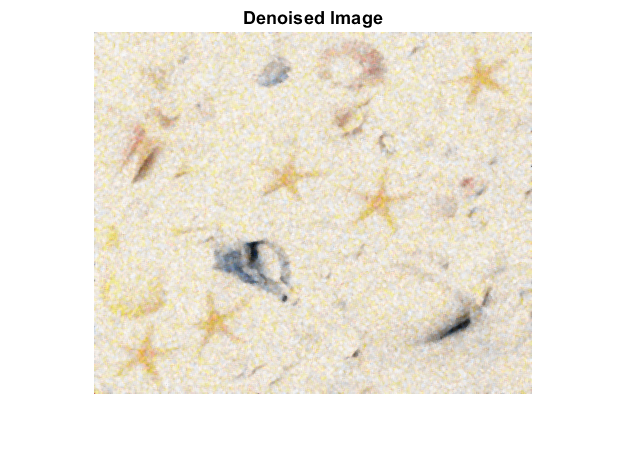

Starfish = imread('starfish.jpg');
Starfish2 = imread('starfish_noise7.jpg');
Starfish3 = imread('starfish_map0.jpg');
Starfish4 = imread('starfish_5.jpg'); 

StarfishDenoise = medfilt3(Starfish2);
GreyStarfish = rgb2gray(StarfishDenoise);
imshow(StarfishDenoise)
title("Denoised Image");

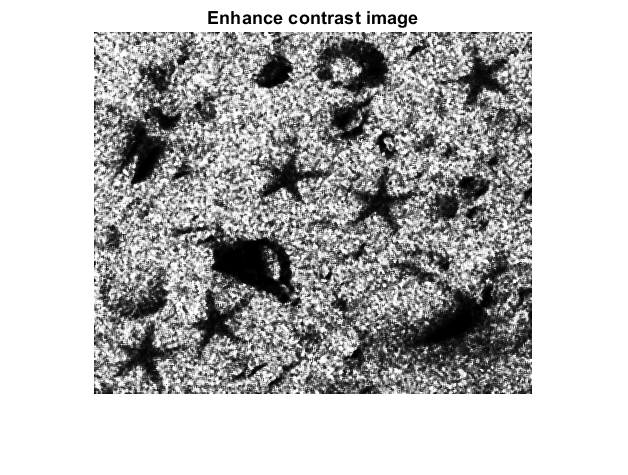


GreyStarfish = histeq(GreyStarfish);
imshow(GreyStarfish);
title("Enhance contrast image");

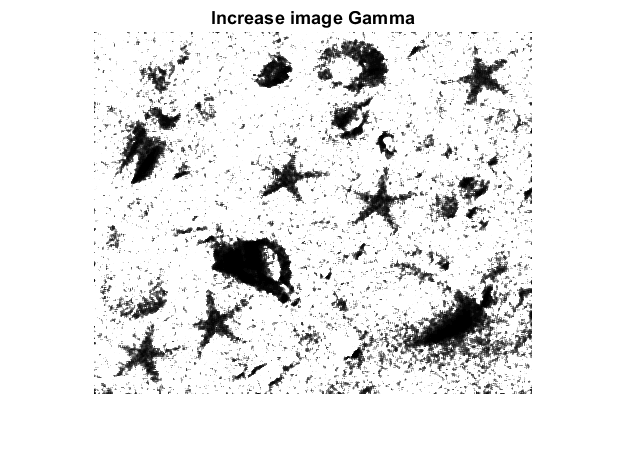

imshow(uint8(double(GreyStarfish) .^1.3));
title("Increase image Gamma");

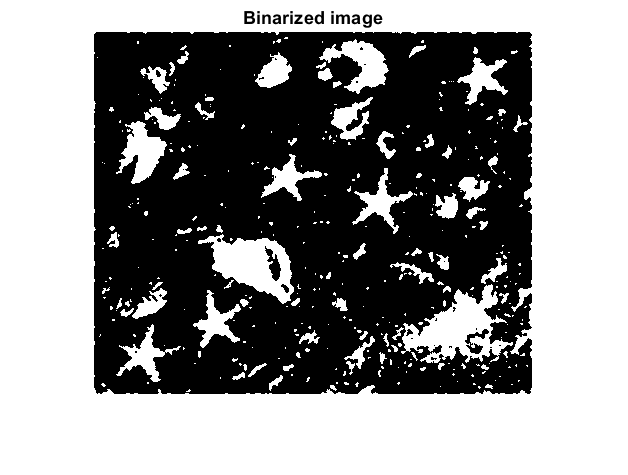

GreyStarfish = uint8(double(GreyStarfish) .^1.3);

% Threshold and binarize the image
thresholdStarfish = graythresh(GreyStarfish);
GreyStarfish = medfilt2(GreyStarfish);
BW1 = imbinarize(GreyStarfish,thresholdStarfish);
BW1 = imcomplement(BW1);
imshow(BW1);
title("Binarized image")

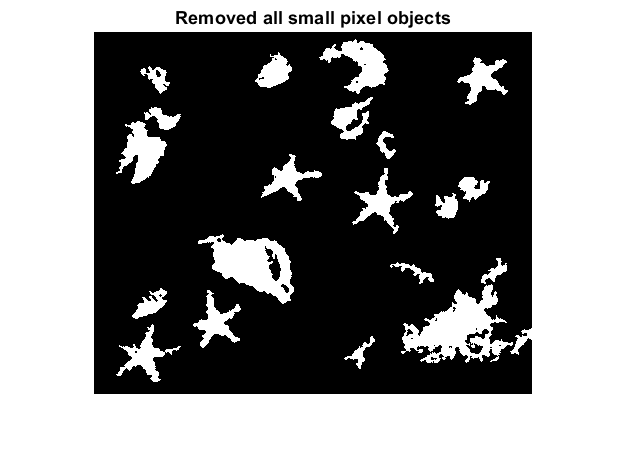


BW2 = bwareaopen(BW1, 200);
imshow(BW2);
title("Removed all small pixel objects")

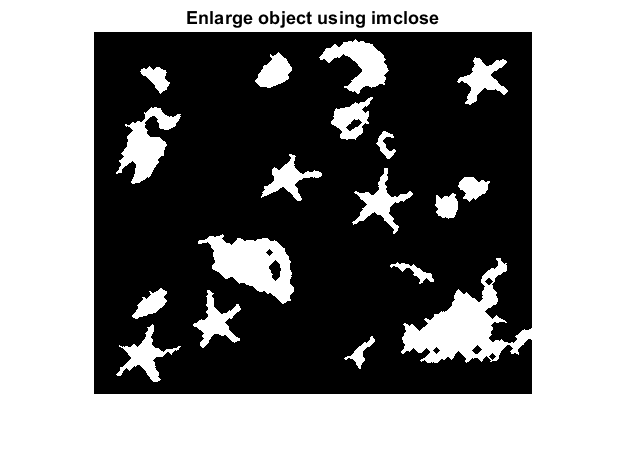


se = strel('diamond',3); 
BW2 = imclose(BW2,se);
imshow(BW2)
title("Enlarge object using imclose");


cc = bwconncomp(BW2)

cc = struct with fields:
    Connectivity: 8
       ImageSize: [362 438]
      NumObjects: 18
    PixelIdxList: {1×18 cell}


info = regionprops(cc,'all');

% Remove any object with hole
labeledImage = bwlabel(BW2);
Hole = [info.EulerNumber]

Hole =      1     1     1     1     1    -1     1     1     1     0     1     1     1     1    -3     1     1     1


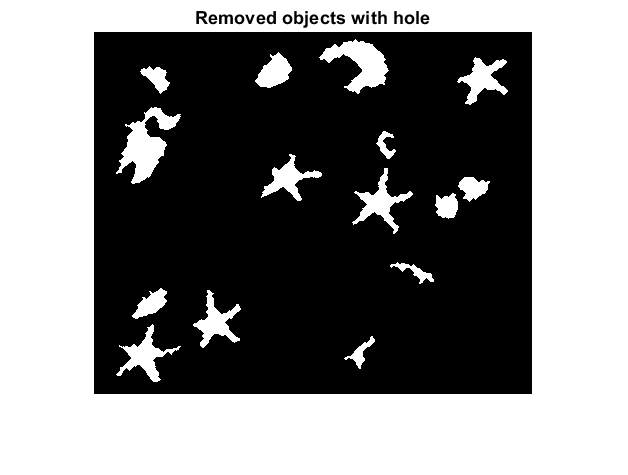

Keep = find(Hole == 1);
BW3 = ismember(labeledImage,Keep) > 0;
imshow(BW3);
title("Removed objects with hole");

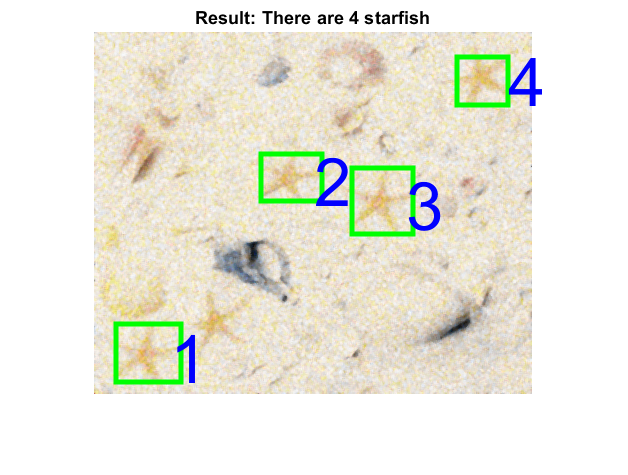



stats = regionprops('table',BW3,'BoundingBox',"Centroid","Area");
[hei, width] = size(BW3);
Count = 0;
figure;
imshow(StarfishDenoise);
hold on
for k = 1 : height(stats)
    stats.Ratio(k) =  (stats.Area(k,1) / numel(BW3))*100;
    stats.HeightRatio(k) = stats.BoundingBox(k,4)/hei;
    stats.WidthRatio(k) = stats.BoundingBox(k,3)/width;
    if(stats.Ratio(k) > 0.56  && stats.Ratio(k) < 0.92 && stats.HeightRatio(k) > 0.125 && stats.WidthRatio(k) > 0.114)
        Count = Count + 1;
        BB = stats.BoundingBox(k,:);
        rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor','g','LineWidth',3) ;
%         H= text(stats.Centroid(k,1) +10, stats.Centroid(k,2),string(k),'color','BLUE','fontsize',44);
        H= text(stats.Centroid(k,1) +25, stats.Centroid(k,2),string(Count),'color','BLUE','fontsize',40);
    end
end
Str = append("Result: There are ", string(Count), " starfish");
title(Str);
hold off